# Get Started with Problem-Based Optimize Live Editor Task

This example script helps you to use the problem-based **Optimize** Live Editor task for optimization or equation solving. Modify the script for your own problem.

The script solves a nonlinear optimization problem with nonlinear constraints:

Minimize ${\rm rosenbrock}(x,y,a)=a(y - x^2)^2 + (1-x)^2$ subject to the constraint $x^2+y^2\le 1$, where $a=100$ and the initial point $x0$ has $x=-2,\ y=2$. Also, impose the bounds $-3\le x\le 3$, $-2\le y\le 9$.

The code for the objective function appears at the end of this script.

## Include Parameters or Data

Typically, you have data or values to pass to the solver. Place those values in the input section (where you see `x0x` and `x0y`) and run the section by choosing **Section > Run Section** or pressing `Control+Enter`.

Set the initial point components `x0x` and `x0y` and scale `a` for the optimization.

x0x = -2;
x0y = 2;
a = 100;

**Place these values and any other problem data into the workspace** by running this section before proceeding.

## Optimize Live Editor Task

Usually, you place the Optimize Live Editor task into the script by selecting **Task > Optimize** in the **Live Editor** tab, or by selecting **Task > Optimize** in the **Insert** tab. Then you are presented with the following choice (this is only a picture, not the real task):

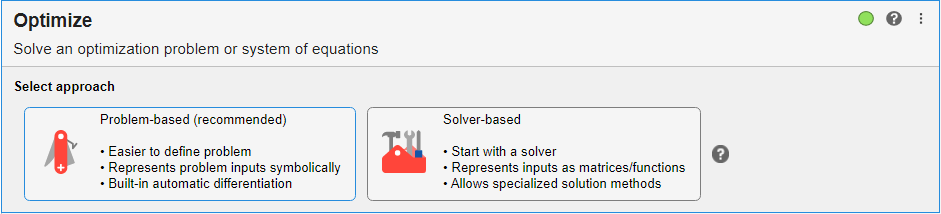

To get the problem-based task, click **Problem-based (recommended)**.

The following problem-based task has the variables, objective, and constraint filled in. Modify it for your problem, or run it as is to see how the task works. To modify the problem, click the **Define problem** button at the bottom of the task. To run the task, click the **Solve problem** button at the bottom of the task.

% Create optimization variables
x13 = optimvar("x1","LowerBound",0,"UpperBound",0.9);
x23 = optimvar("x2","Type","integer","LowerBound",2,"UpperBound",6);
x33 = optimvar("x3","LowerBound",3.31,"UpperBound",6.62);
z33 = optimvar("z3","LowerBound",10,"UpperBound",50);

% Set initial starting point for the solver
initialPoint2.x1 = zeros(size(x13));
initialPoint2.x2 = repmat(5,size(x23));
initialPoint2.x3 = repmat(4,size(x33));
initialPoint2.z3 = repmat(20,size(z33));

% Create problem
problem = optimproblem("ObjectiveSense","Maximize");

% Define problem objective
problem.Objective = fcn2optimexpr(@opt,x13,x23,x33,z33);

% 设置非默认求解器选项
options2 = optimoptions("ga","PlotFcn",["gaplotdistance","gaplotgenealogy",...
    "gaplotscorediversity","gaplotbestf","gaplotbestindiv",...
    "gaplotexpectation"]);

% Display problem information
show(problem);


  OptimizationProblem : 

	Solve for:
       x1, x2, x3, z3
	where:
       x2 integer

	maximize :
       opt(x1, x2, x3, z3)


	variable bounds:
       0 <= x1 <= 0.9

       2 <= x2 <= 6

       3.31 <= x3 <= 6.62

       10 <= z3 <= 50



Solving problem using ga.


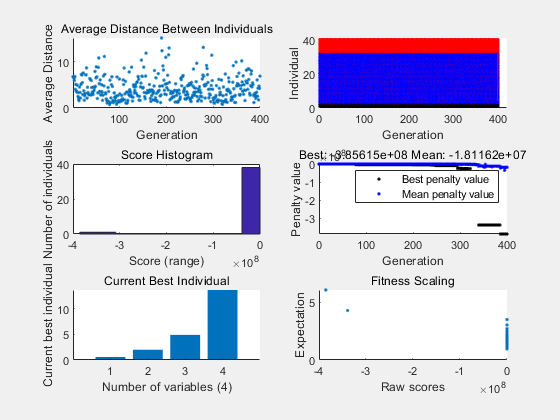

Optimization terminated: maximum number of generations exceeded.



% Solve problem
[solution,~,reasonSolverStopped] = solve(problem,initialPoint2,"Solver","ga",...
    "Options",options2);


% Display results
solution

solution = 包含以下字段的 struct :
    x1: 0.5937
    x2: 2
    x3: 4.8974
    z3: 13.6176


reasonSolverStopped

reasonSolverStopped =     SolverLimitExceeded



% 清除变量
clearvars x13 x23 x33 z33 initialPoint2 options2 reasonSolverStopped

## Interpret Results

The task calls `solve`, which calls `fmincon` to solve the problem. The top of the task shows that the solution is returned in the `solution` structure. The reported solution, `x = 0.7864` and `y = 0.6177`, satisfies the constraint $x^2+y^2\le 1$, as you can see in the following calculation.

solution.x^2 + solution.y^2                                     

无法识别的字段名称 "x"。

The solver reports exit condition `OptimalSolution` when it stops. To interpret this condition, look at the `exitflag` [output of `solve`](docid:optim_ug.mw_cedf587e-dc58-476c-a675-a44b82bff7c5) for the `fmincon` solver. The description states "First-order optimality measure is less than options.OptimalityTolerance, and maximum constraint violation is less than options.ConstraintTolerance." In other words, the solution is a feasible local minimum.

The objective function value at the solution is 0.0457. This is the smallest objective function value among feasible points.

## Helper Functions

This code creates the `rosenbrock` helper function.

function results=opt(x1,x2,x3,z3)%x1,N,W/D,massrate
% global Xl Yl Xd Yd cl_map cd_map cdp_map cdf_map Fx_map Fy_map pinj_map psuc_map Ptinj_map Ptsuc_map Cl_map Cdp_map Cdf_map alpha_map;
    [Xl, Yl] = meshgrid(4:-2:-4, [0.03,0.05,0.06,0.07,0.08,0.09,0.1,0.11,0.12,0.135,0.15,0.16,0.17,0.18,0.2,0.22,0.25,0.275,0.3]); 
    [Xd, Yd] = meshgrid(4:-2:-4, [0.03,0.05,0.1,0.15,0.2,0.25,0.275]); 
    cl_map=table2array(readtable('cl_map_without_jet.xlsx'));
    cd_map=table2array(readtable('cd_map_without_jet.xlsx'));
    cdp_map=table2array(readtable('cdp_map.xlsx'));
    cdf_map=table2array(readtable('cdf_map.xlsx'));
    Fx_map=table2array(readtable('jetFx_map.xlsx'));
    Fy_map=table2array(readtable('jetFy_map.xlsx'));
    pinj_map=table2array(readtable('pinj_map.xlsx'));
    psuc_map=table2array(readtable('psuc_map.xlsx'));
    Ptinj_map=table2array(readtable('Ptinj_map.xlsx'));
    Ptsuc_map=table2array(readtable('Ptsuc_map.xlsx'));
    Cl_map=[0.104,0.296,0.485,0.667234041,0.837096513];
    Cdp_map=[0.007292155,0.007278948,0.008104288,0.009828387,0.012613109];
    Cdf_map=[0.010385784,0.010660165,0.010845842,0.010943995,0.010955707];
    alpha_map=[-4,-2,0,2,4];   
%     0.0299,0.8315,0.1593
%     x1=X(1);
%     x2=X(2);
%     x3=X(3);

    
    Cl=0.54480451;
%     Cl=0;
    Cd_p=0.00893;
    Cd=0.026627649+Cd_p;
    alpha0=2/180*pi;
    real_massrate=z3;
    Q=real_massrate/1.225;
    taper=0.5;
    Gama=11.3099/180*pi;
%     Gama=7.9696/180*pi;
    b=1.5;%半展长
    cr=0.3;%根弦长
    ct=cr*taper;
    S=b*cr*(1+taper)/2;
    cfj_start=x1;%开始展向位置
    A=(1/0.3+0.5*0.1*x3/3);
    B=1/3;
    cfj_end=1/B+(cfj_start-1/B)*(1-0.1*x3*B/A)^x2;%结束展向位置
    if cfj_end>0.99*b
        results=-1000;
        return
    end
    S_cfj=(cfj_end-cfj_start)*(cr*(1-(1-taper)*cfj_start/b)+cr*(1-(1-taper)*(cfj_end/b)))/2;
    
    Ai=40/180*pi;
    As=50/180*pi;
    inj_loc=0.0761;
    suc_loc=0.8107;

    %离散点个数
    N=20;
    Pos=linspace(cfj_start,cfj_end,N+1);
    delta_b=Pos(2:end)-Pos(1:end-1);
    C=cr-(Pos(2:end)+Pos(1:end-1))/2/b*cr*(1-taper);
    Bi_c=0.01;
    Bs_c=0.01*7/3;
    Bi=(Bi_c*cr*(1-(1-taper)*cfj_start/b)+Bi_c*cr*(1-(1-taper)*cfj_end/b))*(cfj_end-cfj_start)/2;
    Bs=(Bs_c*cr*(1-(1-taper)*cfj_start/b)+Bs_c*cr*(1-(1-taper)*cfj_end/b))*(cfj_end-cfj_start)/2;
    
    real_massrate=z3*1.225*(Bi);
    massrate=real_massrate*0.003/Bi;
    Angle_of_inj=atan((b*tan(Gama)+(ct-cr)*inj_loc)/b);
    Angle_of_suc=atan((b*tan(Gama)+(ct-cr)*suc_loc)/b);
    Alpha_i=[0.0341, 0.0323, 0.0308, 0.0297, 0.0289, 0.0282, 0.0277, 0.0272, 0.0270, 0.0269, 0.0269, 0.0271, 0.0274, 0.0278, 0.0285, 0.0295, 0.0309, 0.0330, 0.0361, 0.0418, 0.0527, 0.0610];
    loc_map=linspace(0.0,1.5,22);
    delta_Bi=Bi_c*C.*delta_b;
    delta_Bs=Bs_c*C.*delta_b;
    vinj=real_massrate/1.225/(Bi);
    vsuc=real_massrate/1.225/(Bs);
    Cmiu=real_massrate*vinj/(0.5*1.225*400*S_cfj);

    delta_s=delta_b.*C;
    pinj=zeros(N,1);
    psuc=zeros(N,1);
    ptinj=zeros(N,1);
    ptsuc=zeros(N,1);
    delta_Cl=zeros(N,1);
    delta_Cd=zeros(N,1);
    for i=1:N
    
        loc=(Pos(i+1)+Pos(i))/2;
        alpha_i=interp1(loc_map,Alpha_i,loc, 'linear');
        Cl_eff=interp1(alpha_map,Cl_map,(alpha0/cos(Gama)-alpha_i)/pi*180, 'linear');
        Cdp_eff=interp1(alpha_map,Cdp_map,(alpha0/cos(Gama)-alpha_i)/pi*180, 'linear');
        Cdf_eff=interp1(alpha_map,Cdf_map,(alpha0/cos(Gama)-alpha_i)/pi*180, 'linear');
        old_cl=Cl_eff/cos(alpha_i)-(Cdp_eff+Cdf_eff)*tan(alpha_i)/cos(alpha_i);
        old_cd=(Cdp_eff+Cdf_eff*cos(Gama)^3)/cos(alpha_i)+Cl_eff*tan(alpha_i)/cos(alpha_i)*cos(Gama)^3;

        Cl_eff=interp2(Xl, Yl, cl_map, (alpha0/cos(Gama)-alpha_i)/pi*180, massrate*cos(alpha_i), 'linear');
        Cdp_eff=interp2(Xd, Yd, cdp_map, (alpha0/cos(Gama)-alpha_i)/pi*180, massrate*cos(alpha_i), 'linear');
        Cdf_eff=interp2(Xd, Yd, cdf_map, (alpha0/cos(Gama)-alpha_i)/pi*180, massrate*cos(alpha_i), 'linear');
     
        %垂直1/4弦长处
        new_cl=Cl_eff/cos(alpha_i)-(Cdp_eff+Cdf_eff)*tan(alpha_i)/cos(alpha_i);
        new_cd=(Cdp_eff*cos(Gama)^3+Cdf_eff)/cos(alpha_i)+Cl_eff*tan(alpha_i)/cos(alpha_i)*cos(Gama)^3;
        delta_Cl(i)=new_cl-old_cl;
        delta_Cd(i)= new_cd-old_cd;
        pinj(i)=interp2(Xl, Yl, pinj_map, (alpha0/cos(Gama)-alpha_i)/pi*180, massrate*cos(alpha_i)*cos(Gama-Angle_of_inj), 'linear');
        psuc(i)=interp2(Xl, Yl, psuc_map, (alpha0/cos(Gama)-alpha_i)/pi*180, massrate*cos(alpha_i)*cos(Gama-Angle_of_suc), 'linear');
        ptinj(i)=interp2(Xl, Yl, Ptinj_map, (alpha0/cos(Gama)-alpha_i)/pi*180, massrate*cos(alpha_i)*cos(Gama-Angle_of_inj), 'linear');
        ptsuc(i)=interp2(Xl, Yl, Ptsuc_map, (alpha0/cos(Gama)-alpha_i)/pi*180, massrate*cos(alpha_i)*cos(Gama-Angle_of_suc), 'linear');
    %             Cd_p(i)=DeltaCd_p(i)*cos(Gama)^3/cos(alpha_i);
    %             Cd_f(i)=DeltaCd_f(i)/cos(alpha_i);
    end
        Cl_no_jet=Cl+delta_s*delta_Cl;
        Cd_no_jet=Cd+delta_s*delta_Cd;
        fj_x=((vinj)*real_massrate)*cos(Ai-alpha0)+delta_Bi*pinj*cos(Ai-alpha0);
        fs_x=-(-(vsuc)*real_massrate)*cos(As+alpha0)-delta_Bs*psuc*cos(As+alpha0);
        fj_y=((vinj)*real_massrate)*sin(Ai-alpha0)+delta_Bi*pinj*sin(Ai-alpha0);
        fs_y=(-(vsuc)*real_massrate)*sin(As+alpha0)+delta_Bs*psuc*sin(As+alpha0);
        Cl=Cl_no_jet-fj_y/(0.5*1.225*400*S)-fs_y/(0.5*1.225*400*S);
        Cd=Cd_no_jet-fj_x/(0.5*1.225*400*S)*cos(Angle_of_inj)-fs_x/(0.5*1.225*400*S)*cos(Angle_of_suc);
        K=0.0259*x3^2-0.1178*x3+0.2967;
        DeltaP=delta_Bs*(ptinj-ptsuc)/Bs+K*0.5*1.225*vinj^2;
        K=0.0259*x3^2-0.1178*x3+0.2967;
        M_duct=0;
        for i=1:x2
            P_loc=1/B+(cfj_start-1/B)*((1-0.1*x3*B/A)^i+(1-0.1*x3*B/A)^(i-1))/2;%结束展向位置
            c_loc=cr*(1-(1-taper)*P_loc/b);
            M_duct=1300*0.002*(Bi_c+Bs_c+2*x3+pi*0.1)*c_loc;
        end
        m0=36.774;
        mp=8;
        Pd=3000;
        ETA=0.7;
        M_motor=Q*DeltaP/ETA/Pd;
        m_CFJ=M_duct+M_motor;

        results=(1-(mp+m_CFJ)/m0-0.3)/(1-mp/m0-0.3)*Cl/(Cd+Q*DeltaP/(ETA*0.5*1.225*20^3*S));

    

end

*Copyright 2021 The MathWorks, Inc.*